% Script to test a homing routine for steering servo motors

% First, create some random data representing the analog potentiometer
% values coming in

% Number of startup measurements to sample from the potentiometer to get
% the initial startup position
N = 50;
% Choose an arbitrary true startup position
x_true_startup = 21*pi/180;
% Simulate measuring the startup position with noise from the pot
x_meas_startup = x_true_startup + randn(N,1)*pi/180;
% Set the location of the true home and the true index pulses
x_true_home = -0.015;
x_true_index = (-2.5*pi/180*10:2.5*pi/180:2.5*pi/180*10)';
x_home_index_offset = x_true_home - x_true_index(19);

% Calculate the best estimate of the startup position from the average pot
% reading
x_calc_startup = mean(x_meas_startup);
% Compute the measurement offset from the true position
x_meas_offset = x_calc_startup - x_true_startup;

% Simulate a slightly noisy acquisition of the encoder counts at the home
% position
x_meas_home = x_true_home + x_meas_offset + (1/10)*randn(1,1)*pi/180;
% Simulate a perfectly accurate acquisition of the encoder counts at a
% nearby index pulse
idx = find(abs(x_true_index - x_meas_home) <= 1.25*pi/180,1,'first');
x_meas_index = x_true_index(idx) + x_meas_offset;

% Calculate the offset between the known true home position and the
% acquired home position
x_meas_home_offset = (x_meas_home - x_true_home);

% Calculate the difference between the acquired home position and the
% acquired index position. This should be less than 2.5 degrees. If not,
% the index pulse that was captured was not the home index pulse
x_meas_index_home_diff = x_meas_index - x_meas_home;

% Adjust to make sure that the index pulse being referenced is the "zero"
% index pulse. The true zero will be to the negative side of the home
% switch between 0 and -2.5 degrees.
while x_meas_index - x_meas_home > 0
    x_meas_index = x_meas_index - 2.5*pi/180;
end
while x_meas_index - x_meas_home < -2.5*pi/180
    x_meas_index = x_meas_index + 2.5*pi/180;
end

% Calculate the final offset
x_final_offset = x_meas_index - x_true_index(idx)

x_final_offset = -0.0400

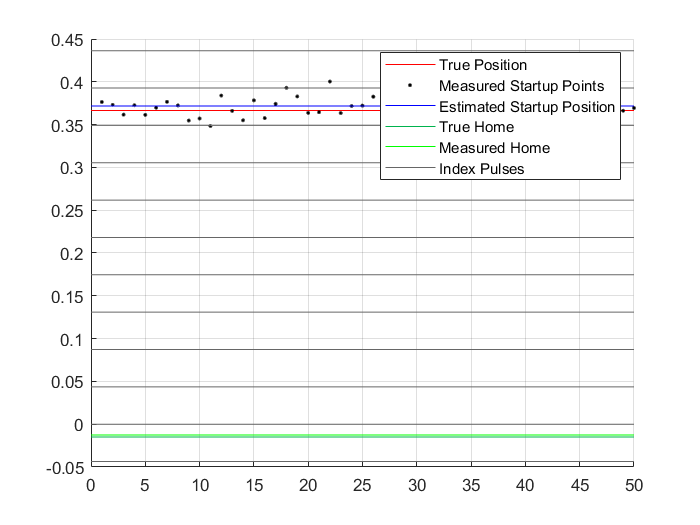


% Plot the results
figure(1)
clf
axis auto
hold on
grid on
plot([0 N],[1 1]*x_true_startup,'r-')
plot((1:N)',x_meas_startup,'k.');
plot([0 N],[1 1]*x_calc_startup-x_calc_offset,'b-')
plot([0 N],[1 1]*x_true_home,'-','color',[0 0.7 0.3])
plot([0 N],[1 1]*x_meas_home,'g-')
axis manual
for i = 1:length(x_true_index)
    plot([0 N],[1 1]*x_true_index(i),'color',0.4*ones(1,3))
end
legend('True Position','Measured Startup Points','Estimated Startup Position','True Home','Measured Home','Index Pulses')